**Part I : Linear Regression.**

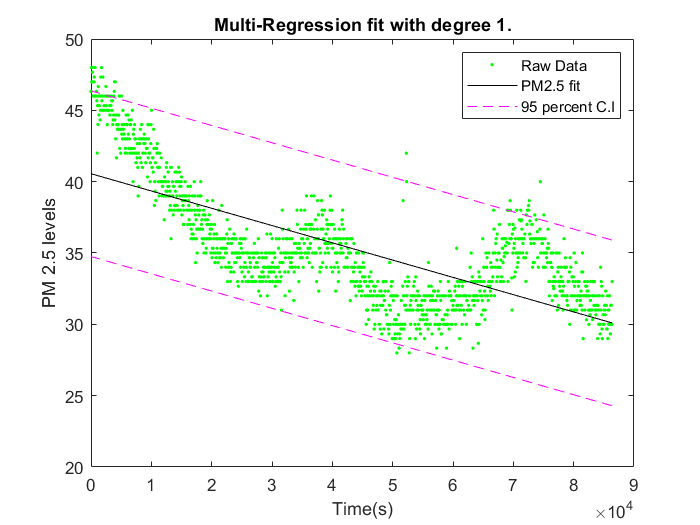

%Part 1
clear
load hw3_1.mat
pm2d5= data.pm2d5;
time = data.time;
time_second = (datenum(time)-floor(datenum(time)))*24*60*60;

figure
degree= 1;
[p1, SI]= polyfit(normalize(time_second,'zscore'), pm2d5,degree);
[yfit, delta] = polyval(p1, normalize(time_second,'zscore'), SI);
plot(time_second, pm2d5, '.g');
hold on
plot(time_second, yfit, 'k');
plot(time_second,yfit+2*delta,'m--',time_second,yfit-2*delta,'m--');
header = sprintf("Multi-Regression fit with degree %.0f.", degree);
title(header), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','PM2.5 fit','95 percent C.I');
hold off

a) See above.

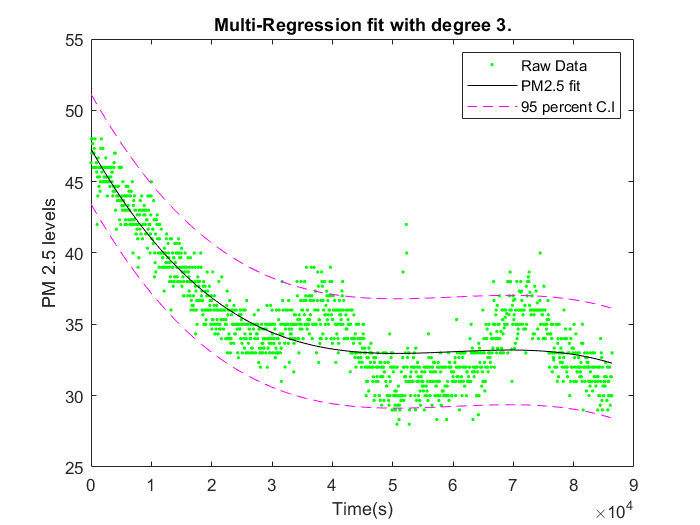

figure
degree= 3;
[p1, SI]= polyfit(normalize(time_second,'zscore'), pm2d5,degree);
[yfit, delta] = polyval(p1,normalize(time_second,'zscore'), SI);
plot(time_second, pm2d5, '.g');
hold on
plot(time_second, yfit, 'k');
plot(time_second,yfit+2*delta,'m--',time_second,yfit-2*delta,'m--');
header = sprintf("Multi-Regression fit with degree %.0f.", degree);
title(header), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','PM2.5 fit','95 percent C.I');
hold off

b) Polynomial degree 3 seems to capture the overall trend of PM 2.5 data (changes in local gradients) much better than the linear fit (degree 1).

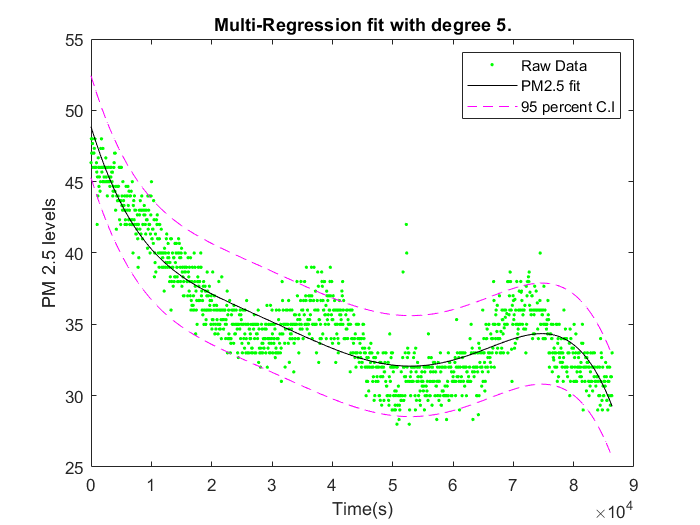

figure
degree= 5;
[p1, SI]= polyfit(normalize(time_second,'zscore'), pm2d5,degree);
[yfit, delta] = polyval(p1, normalize(time_second,'zscore'), SI);
plot(time_second, pm2d5, '.g');
hold on
plot(time_second, yfit, 'k');
plot(time_second,yfit+2*delta,'m--',time_second,yfit-2*delta,'m--');
header = sprintf("Multi-Regression fit with degree %.0f.", degree);
title(header), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','PM2.5 fit','95 percent C.I');
hold off

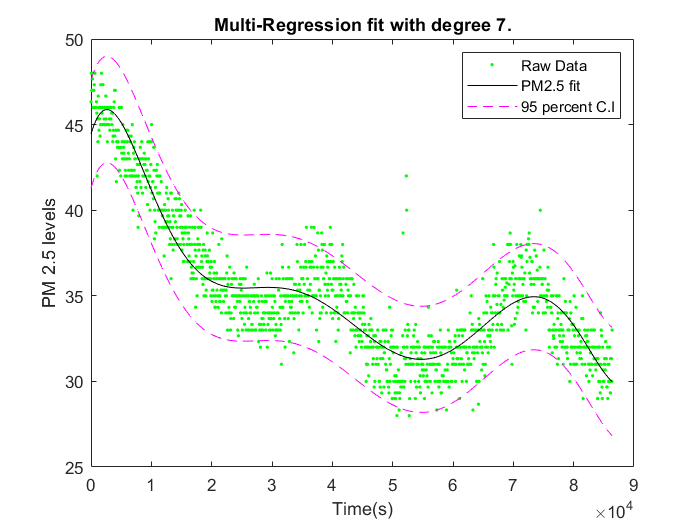

figure
degree= 7;
[p1, SI]= polyfit(normalize(time_second,'zscore'), pm2d5,degree);
[yfit, delta] = polyval(p1, normalize(time_second,'zscore'), SI);
plot(time_second, pm2d5, '.g');
hold on
plot(time_second, yfit, 'k');
plot(time_second,yfit+2*delta,'m--',time_second,yfit-2*delta,'m--');
header = sprintf("Multi-Regression fit with degree %.0f.", degree);
title(header), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','PM2.5 fit','95 percent C.I');
hold off

figure
degree= 50;
[p1, SI]= polyfit(normalize(time_second,'zscore'), pm2d5,degree);

[yfit, delta] = polyval(p1, normalize(time_second,'zscore'), SI);

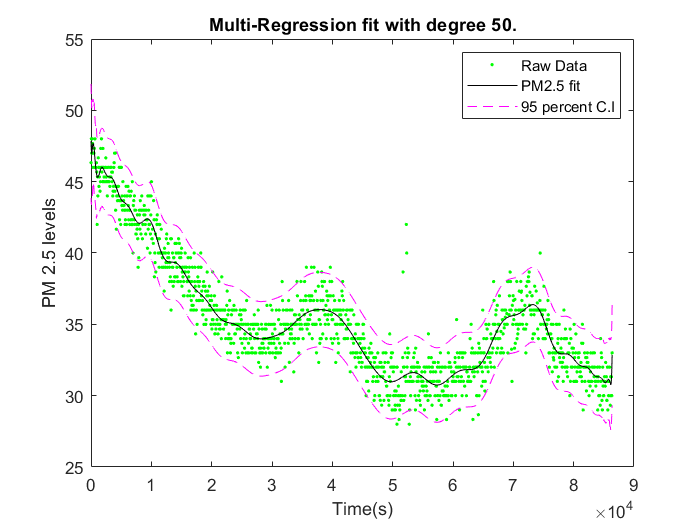

plot(time_second, pm2d5, '.g');
hold on
plot(time_second, yfit, 'k');
plot(time_second,yfit+2*delta,'m--',time_second,yfit-2*delta,'m--');
header = sprintf("Multi-Regression fit with degree %.0f.", degree);
title(header), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','PM2.5 fit','95 percent C.I');
hold off

c) As the polynomial degree increases from 1 to 7, the fit seems to capture the trend and seasonality of data much better. However, when you increase the degree to 50, the polynomial seems to capture the potential noise spikes too, which is not desirable.

d) I believe degree 7 polynomial fit seems to represent the data the best because it captures the overall trend and seasonality without overfitting to the data noises. The benefit of the higher degree polynomial fit is that it captures the micro changes in seasonality and trend of the observation data. However, after a certain point, the high degree polynomial seems to overfit the potential noises in the data, at which point the fit becomes non-generalizable to unseen data. 

**Part II: Regularization + Other Factors**

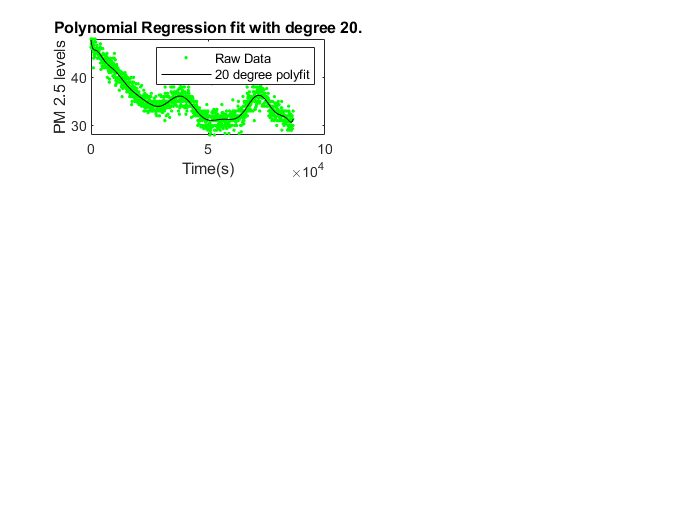

%Part 2

%20 degree polynomial fit
figure
subplot(3,2,1)
degree= 20;
[p1, SI]= polyfit(normalize(time_second,'zscore'), pm2d5,degree);
[yfit_20, delta] = polyval(p1, normalize(time_second,'zscore'), SI);
plot(time_second, pm2d5, '.g');
hold on
plot(time_second, yfit_20, 'k');
header = sprintf("Polynomial Regression fit with degree %.0f.", degree);
title(header), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','20 degree polyfit');
hold off

a) See above.

b) The cost function of Ridge Regression is the Residual Sum Squares + Regularization factor:

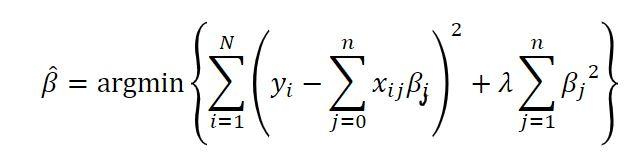


$$\begin{array}{l}
\textrm{where}\;N=\textrm{number}\;\textrm{of}\;\textrm{data}\;\textrm{samples},n=\textrm{number}\;\textrm{of}\;\textrm{input}\;\textrm{features},\beta =\textrm{learnable}\;\textrm{coefficients},\\
\beta^ˆ =\textrm{optimal}\;\textrm{coefficient}\;\textrm{that}\;\textrm{minimizes}\;\textrm{cost}\;\textrm{function},x=\textrm{input}\;\textrm{data},\textrm{and}\;y=\textrm{ground}\;\textrm{truth}\;\textrm{output}\;\textrm{data}\\
\lambda =\textrm{Regularization}\;\textrm{term}
\end{array}$$


The equation has a closed form solution for polynomial curve fitting:

where:

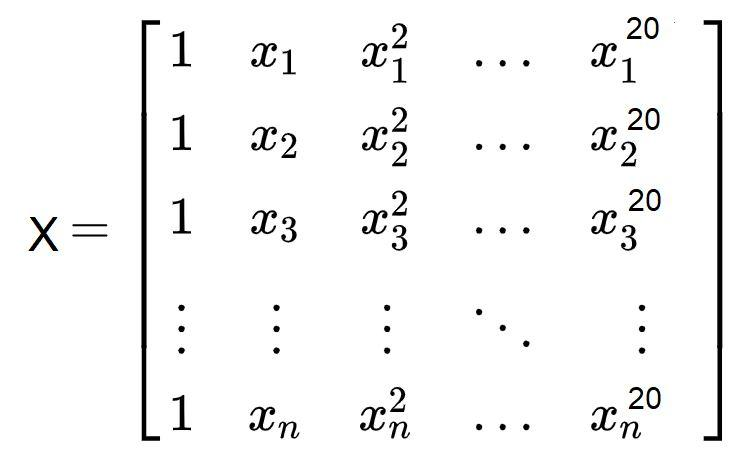 and Y= Ground Truth PM2.5 data from $y_{1\;} \textrm{to}\;y_{n\;}$

c) The cost function of LASSO regression:

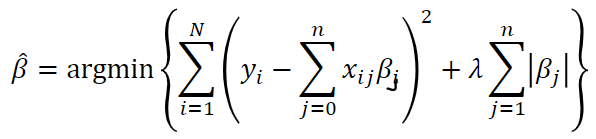


$$\begin{array}{l}
\textrm{where}\;N=\textrm{number}\;\textrm{of}\;\textrm{data}\;\textrm{samples},n=\textrm{number}\;\textrm{of}\;\textrm{input}\;\textrm{features},\beta =\textrm{learnable}\;\textrm{coefficients},\\
\beta^ˆ =\textrm{optimal}\;\textrm{coefficient}\;\textrm{that}\;\textrm{minimizes}\;\textrm{cost}\;\textrm{function},x=\textrm{input}\;\textrm{data},\textrm{and}\;y=\textrm{ground}\;\textrm{truth}\;\textrm{output}\;\textrm{data}\\
\lambda =\textrm{Regularization}\;\textrm{term}
\end{array}$$


From the cost function equation we can see that LASSO is different from Ridge Regression because the Regularization term is multiplied to the absolute value of the sum of coefficients rather than the square of the sum of coefficients. This helps with dimensionality reduction of input features and also reduces the effects of outlier data on optimal coefficient determination.

This cost function does NOT have a closed form solution like Ridge Regression.

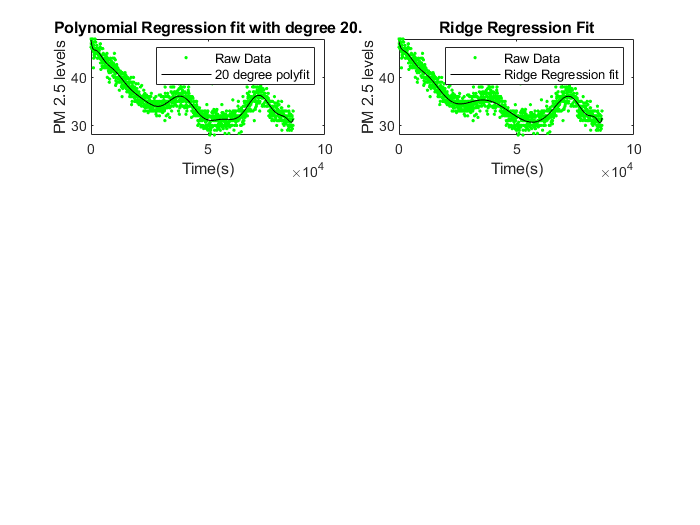


%Creating Vandermonde Matrix of degree 20
dim= 20;
num_d= length(time_second);
V_m= ones(num_d,dim+1);
for i= 1:dim+1
    V_m(:,i)= normalize(time_second,'zscore').^(dim+1-i);
end

%Ridge Regression
Y= pm2d5;
lambda = 0.1;
dim = size(V_m,2);
beta = inv((V_m'*V_m)+lambda*eye(dim))*V_m'*Y;
y_fit_ridge = V_m*beta;
subplot(3,2,2)
plot(time_second,Y,'.g')
hold on
plot(time_second, y_fit_ridge,'k')
title('Ridge Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','Ridge Regression fit');
hold off

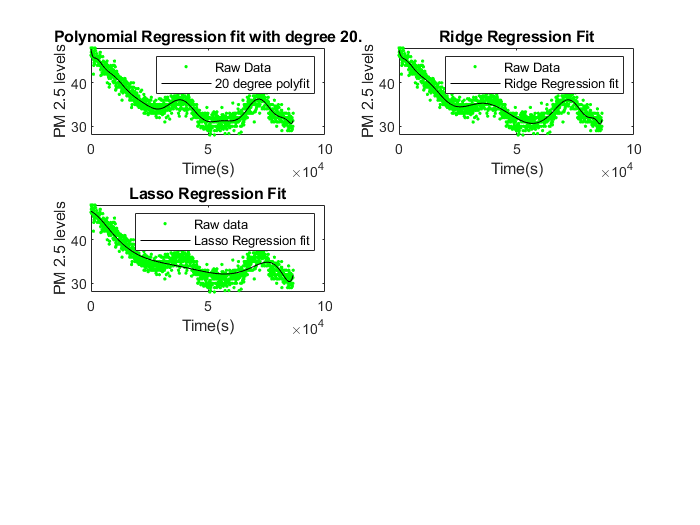

%LASSO
lambda=0.01;
[Beta, Fitinfo] = lasso(V_m,Y,'Lambda',lambda);
intercept=Fitinfo.Intercept;
y_fit_lasso = V_m*Beta+intercept;
subplot(3,2,3)
plot(time_second,Y,'.g')
hold on
plot(time_second, y_fit_lasso,'k')
title('Lasso Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw data','Lasso Regression fit');
hold off

d) $\lambda =0\ldotp 1$ seems to work best for the Ridge Regression fit and $\lambda =0\ldotp 01$ works best for the LASSO fit. The Ridge Regression and LASSO fits seem to work better with the overall trend, without overfitting to the outliers data- especially around $5\times {10}^{4\;} s$.

LASSO regression's coefficients seem much more constant around 0 compared to Ridge Regression's coefficients:

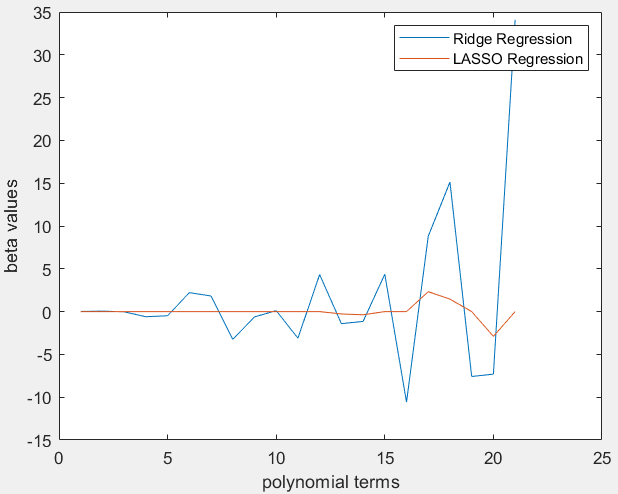 

This is likely the reason why LASSO fit's plot looks underfitted compared to Ridge Regression's fit because LASSO has more 0 values- hence more dimensions reduced.

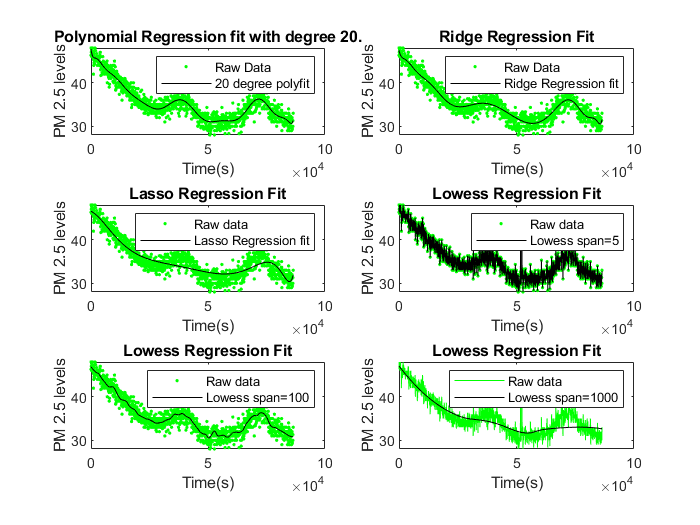

%LOWESS
span = 5;
ysmooth =smooth(time_second,Y,span,'loess');
subplot(3,2,4)
plot(time_second, Y,'.g')
hold on
plot(time_second, ysmooth,'k')
title('Lowess Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw data','Lowess span=5');
hold off

span = 100;
ysmooth =smooth(time_second,Y,span,'loess');
subplot(3,2,5)
plot(time_second, Y,'.g')
hold on
plot(time_second, ysmooth,'k')
title('Lowess Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw data','Lowess span=100');
hold off

span = 1000;
ysmooth =smooth(time_second,Y,span,'loess');
subplot(3,2,6)
plot(time_second, Y,'g')
hold on
plot(time_second, ysmooth,'k')
title('Lowess Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw data','Lowess span=1000');
hold off

e) From the last 3 subplots, we see that as the span of LOWESS smoothing increases its fitting to raw data decreases. LOWESS with span 5 seems to excessively overfit the data while span 1000 seems to miss some changes in overall data trend. Hence, LOWESS smoothing with span=100 seems to best represent the data which captures the overall trend without overfitting.

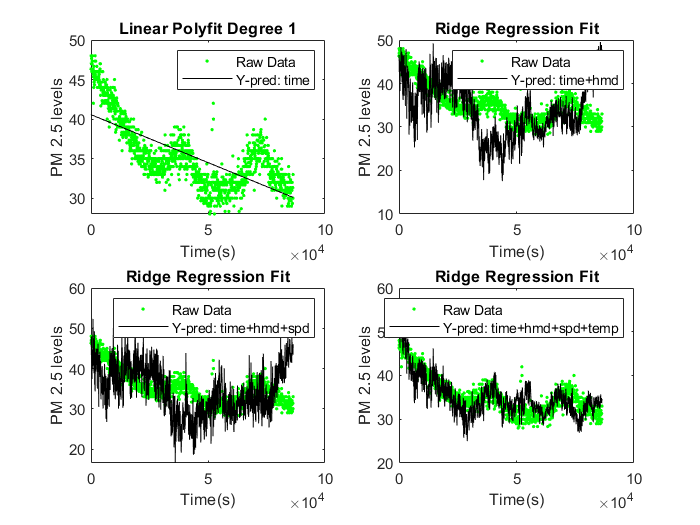

%Linear Regression with multiple features using Ridge Regression

lambda =0.1;
figure
subplot(2,2,1)
degree= 1;
[p1, SI]= polyfit(normalize(time_second,'zscore'), pm2d5,degree);
[yfit, delta] = polyval(p1, normalize(time_second,'zscore'), SI);
plot(time_second, pm2d5, '.g');
hold on
plot(time_second, yfit, 'k');
title('Linear Polyfit Degree 1'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','Y-pred: time');
hold off

X= [normalize(time_second,'range'), normalize(data.hmd,'range')];
Y= pm2d5;
dim = size(X,2);
beta = inv((X'*X)+lambda*eye(dim))*X'*Y;
y_fit_ridge = X*beta;
subplot(2,2,2)
plot(time_second,Y,'.g')
hold on
plot(time_second, y_fit_ridge,'k')
title('Ridge Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','Y-pred: time+hmd');
hold off

X= [normalize(time_second,'range'), normalize(data.hmd,'range'),normalize(data.spd,'range')];
dim = size(X,2);
beta = inv((X'*X)+lambda*eye(dim))*X'*Y;
y_fit_ridge = X*beta;
subplot(2,2,3)
plot(time_second,Y,'.g')
hold on
plot(time_second, y_fit_ridge,'k')
title('Ridge Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','Y-pred: time+hmd+spd');
hold off

X= [normalize(time_second,'range'), normalize(data.hmd,'range'),normalize(data.spd,'range'),normalize(data.tmp,'range')];
dim = size(X,2);
beta = inv((X'*X)+lambda*eye(dim))*X'*Y;
y_fit_ridge = X*beta;
subplot(2,2,4)
plot(time_second,Y,'.g')
hold on
plot(time_second, y_fit_ridge,'k')
title('Ridge Regression Fit'), xlabel('Time(s)'), ylabel('PM 2.5 levels'), legend('Raw Data','Y-pred: time+hmd+spd+temp');
hold off

f) From the plots above, we see that as we add more features to the data, the linear fit seems to improve. While adding humidity and wind speed features to time seems to improve the fit compared to just time, adding temperature to the features seems to best improve the fit of the data.The last 2 plots prove this statement.